clc;clear;
a = (0:8).^2;
b = 0:8;
v = 0:0.1:64;

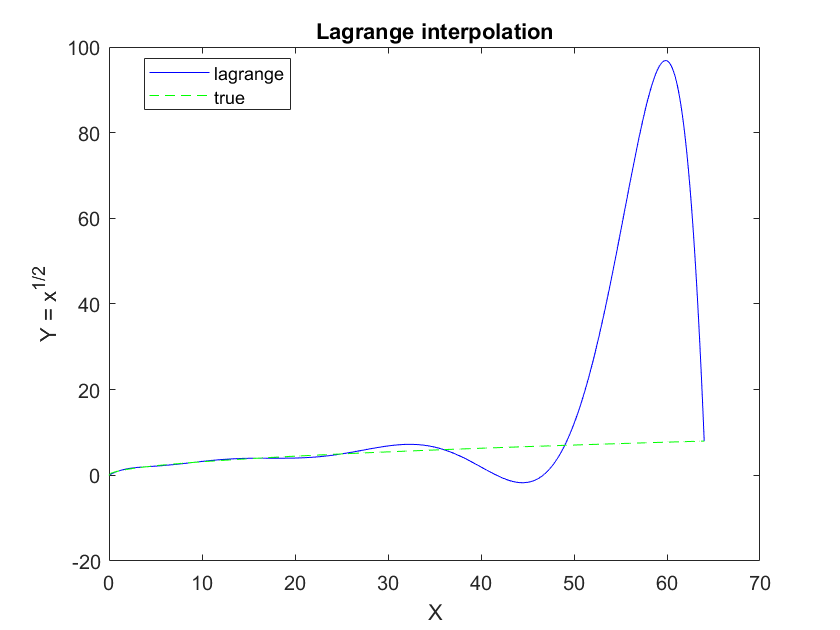

y_lag = Lag(a,b',v');
plot(v,y_lag,'b-')
hold on;
plot(v,v.^0.5,"g--")
% xlim([0,1]);
legend({'lagrange','true'},'Location','best')
title('Lagrange interpolation')
xlabel('X')
ylabel('Y = x^{1/2}')
hold off;

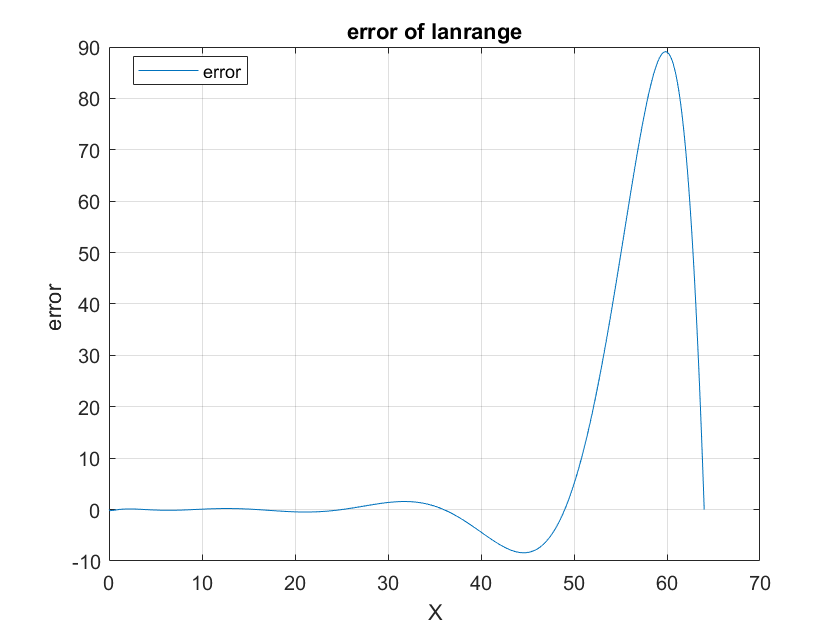

err_lag = y_lag-(v.^0.5)';
plot(v,err_lag)
grid;
legend({'error'},'location','best')
title('error of lanrange')
xlabel('X')
ylabel('error ')

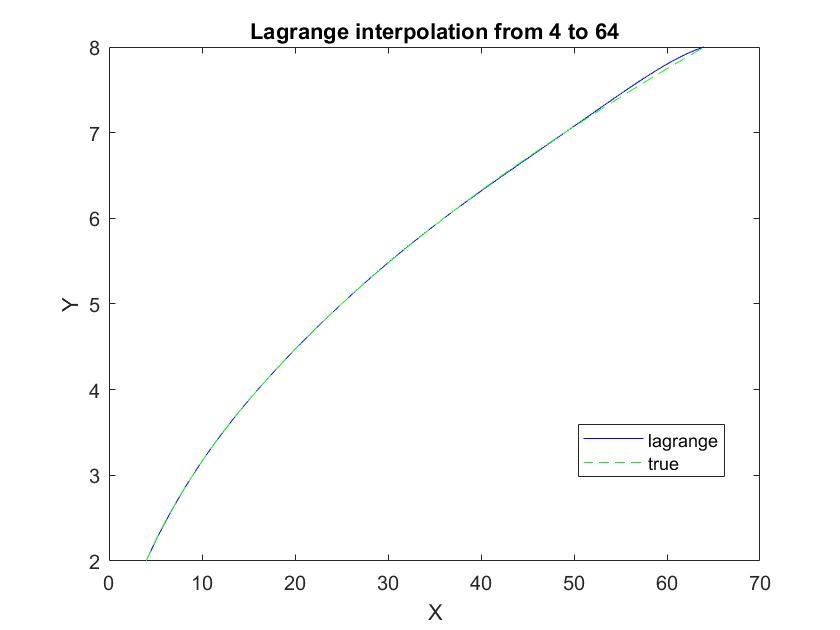

y_lag1 = Lag((2:8).^2,(2:8)',(4:0.1:64)');
err_lag_1=y_lag1 - ((4:0.1:64).^(0.5))';
plot(4:0.1:64, y_lag1,"b-");
hold on
plot(4:0.1:64,(4:0.1:64).^(0.5),"g--")
legend({'lagrange','true'},'Location','best')
xlabel('X')
ylabel('Y')
title('Lagrange interpolation from 4 to 64')
hold off

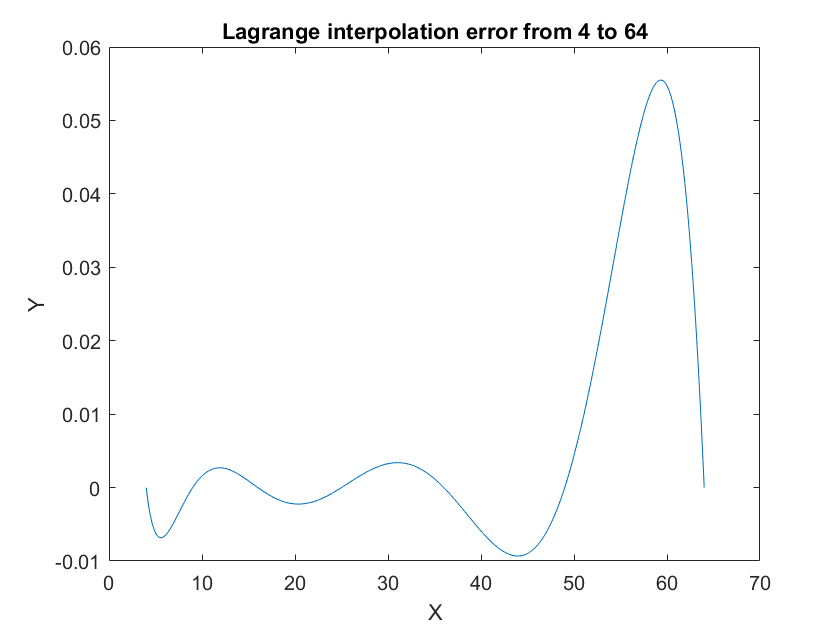

plot(4:0.1:64,err_lag_1)
xlabel('X')
ylabel('Y')
title('Lagrange interpolation error from 4 to 64')

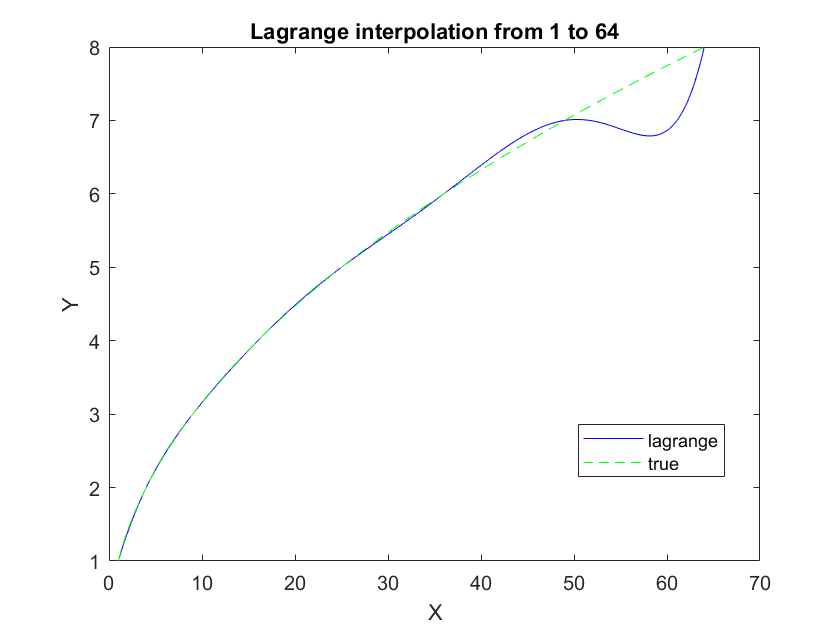

y_lag2 = Lag((1:8).^2,(1:8)',(1:0.1:64)');
err_lag_2=y_lag2 - ((1:0.1:64).^(0.5))';
plot(1:0.1:64, y_lag2,"b-");
hold on
plot(1:0.1:64,(1:0.1:64).^(0.5),"g--")
legend({'lagrange','true'},'Location','best')
xlabel('X')
ylabel('Y')
title('Lagrange interpolation from 1 to 64')
hold off

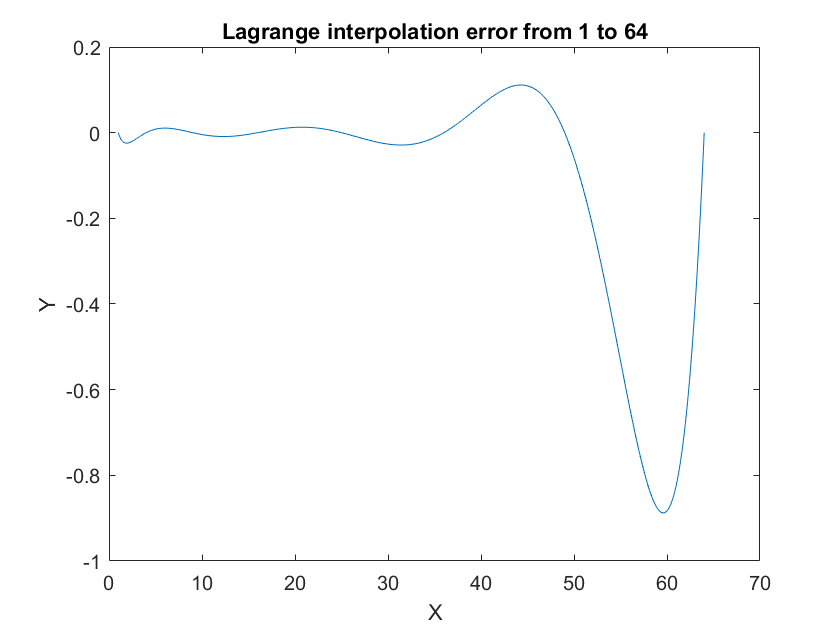

plot(1:0.1:64,err_lag_2)
xlabel('X')
ylabel('Y')
title('Lagrange interpolation error from 1 to 64')

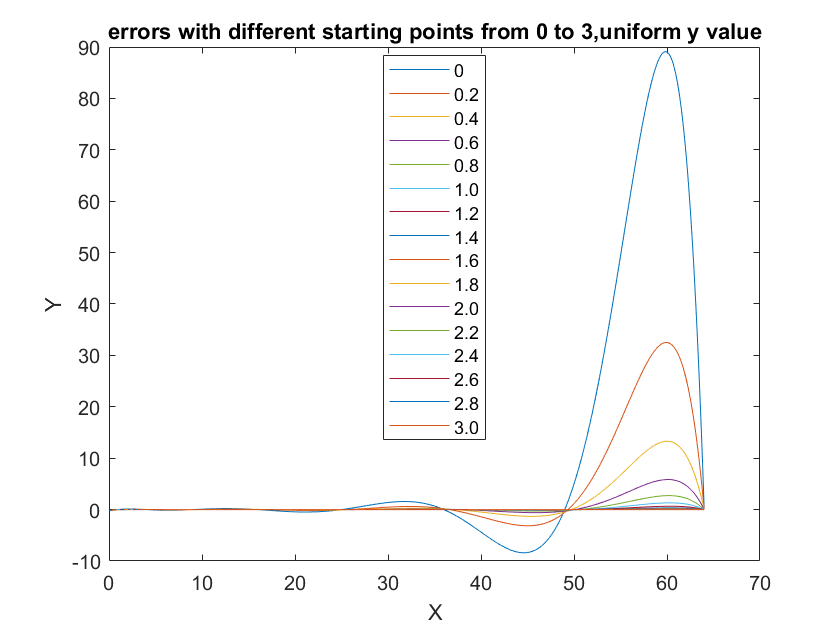

i = 1;
err_ma = zeros(600,16);
for st = 0:0.2:3
    u = linspace(st,64,600);
    v = u.^(0.5);
    u_in = linspace(st,8,9).^2;
    v_in = linspace(st,8,9);
    err_ma(:,i) = Lag(u_in,v_in',u')-v';
    plot(u,err_ma(:,i));
    hold on
    i = i+1;
end
hold off

legend({'0','0.2','0.4','0.6','0.8','1.0','1.2','1.4','1.6','1.8','2.0','2.2','2.4','2.6','2.8','3.0'},'location','best')
title('errors with different starting points from 0 to 3,uniform y value')
xlabel('X')
ylabel('Y')

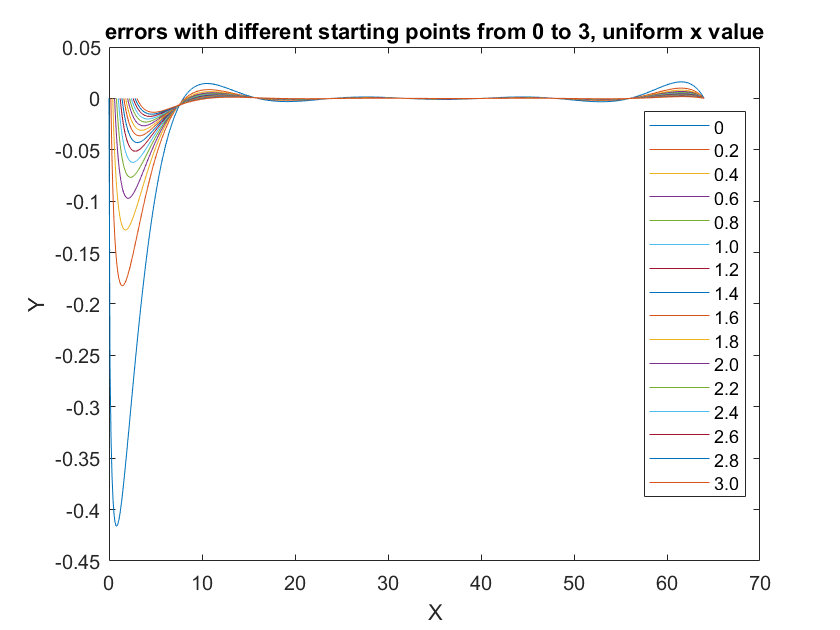

i = 1;
err_ma2 = zeros(600,16);
for st = 0:0.2:3
    u = linspace(st,64,600);
    v = u.^(0.5);
    u_in = linspace(st,64,9);
    v_in = u_in.^(0.5);
    err_ma2(:,i) = Lag(u_in,v_in',u')-v';
    plot(u,err_ma2(:,i));
    hold on
    i = i+1;
end
hold off

legend({'0','0.2','0.4','0.6','0.8','1.0','1.2','1.4','1.6','1.8','2.0','2.2','2.4','2.6','2.8','3.0'},'location','best')
title('errors with different starting points from 0 to 3, uniform x value')
xlabel('X')
ylabel('Y')

aa = (1:8).^2;
bb(2:9)=1:8;
bb(1) = 0.5;
bb(10) = 0.5*64^(-0.5);
y_spl = spline(aa',bb',(1:0.1:64));
plot(1:0.1:64,y_spl,"r-")
hold on;
plot(v,v.^0.5,"g--")
xlim([0,64])
legend({'Spline','true'},'Location','best')
title('Cubic Spline interpolation')
xlabel('X')
ylabel('Y = x^{1/2}')
hold off;

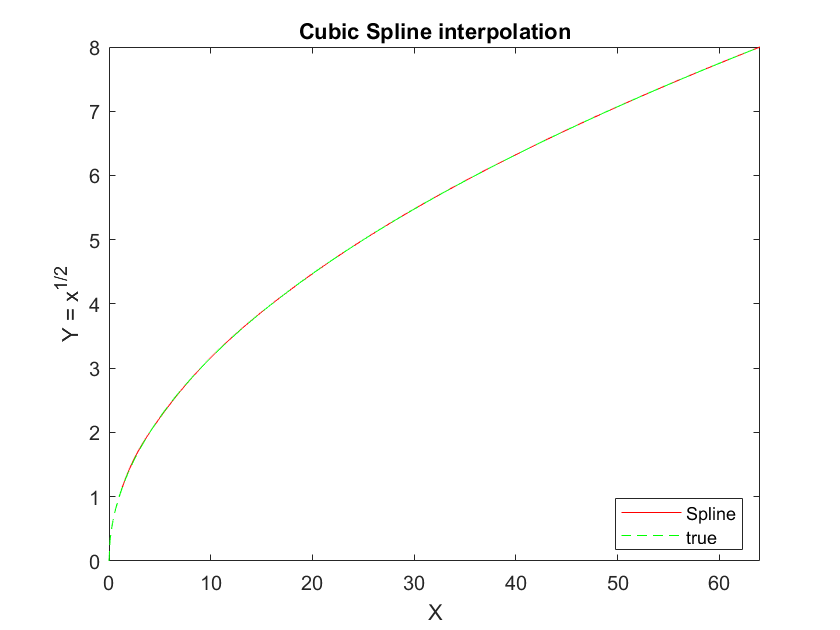

err_spl = y_spl - (1:0.1:64).^(0.5);
plot(1:0.1:64,err_spl);

grid;
legend({'error'},'location','best')
title('error of cubic spline')
xlabel('X')
ylabel('error ')

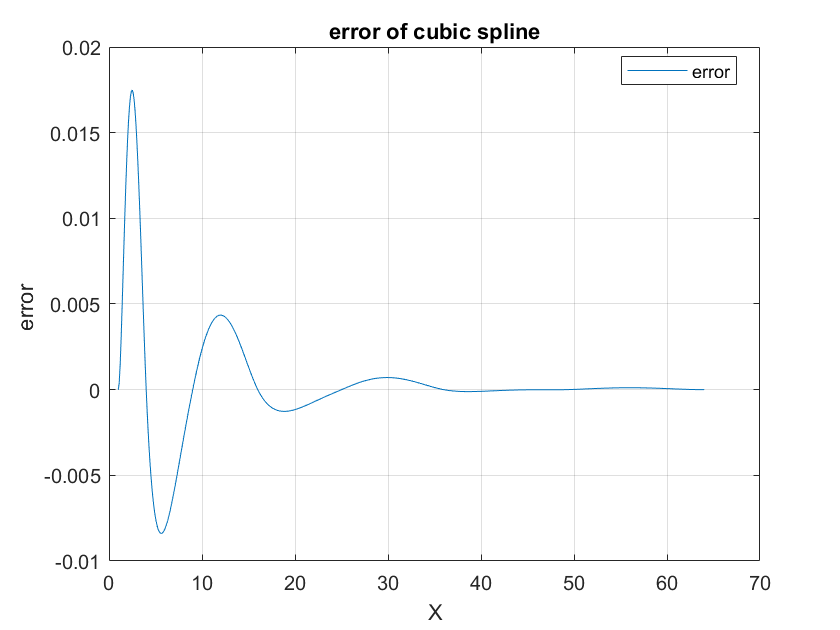

bbb(2:10) = b.*a;
bbb(1) = 0;
bbb(11)= 12; 

v = 0:0.01:1;
y_spl = spline(a',bbb',v);
y(2:101) = y_spl(2:101)./(0.01:0.01:1);
y(1) = 0;
plot(0:0.01:1,y,"r-")
hold on;
plot(v,v.^0.5,"g--")
plot(0:0.1:64,y_lag,'b-')
xlim([0,1])
legend({'Spline','true','lagrange'},'Location','best')
title('Cubic Spline vs Lagrange')
xlabel('X')
ylabel('Y = x^{1/2}')
hold off;

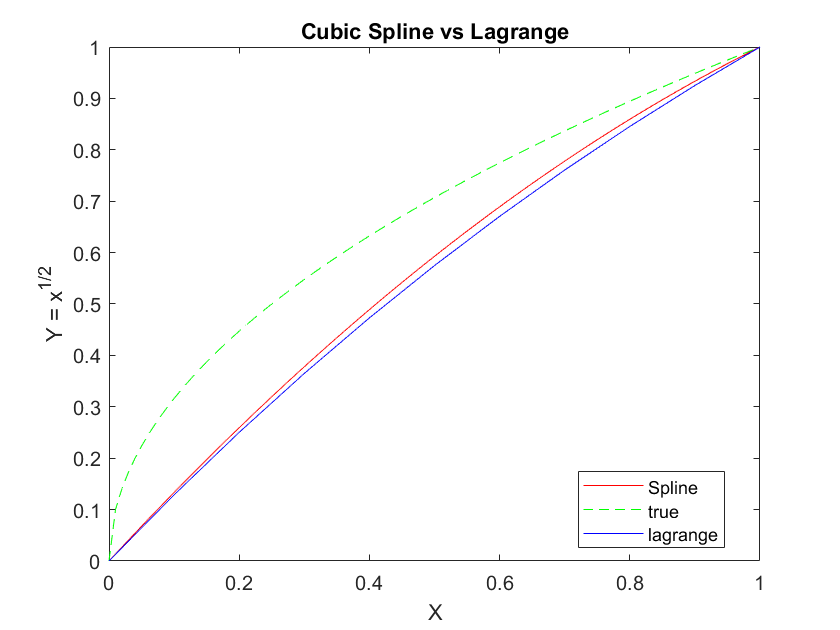

bbb(2:10) = b.*a;
bbb(1) = 0;
bbb(11)= 12; 
v = 0:0.1:64;

y_spl = spline(a',bbb',v);
y(2:641) = y_spl(2:641)./(0.1:0.1:64);
y(1) = 0;
plot(0:0.1:64,y,"r-")
hold on;
plot(v,v.^0.5,"g--")
plot(0:0.1:64,y_lag,'b-')
legend({'Spline','true','lagrange'},'Location','best')
title('Cubic Spline vs Lagrange on [0,64]')
xlabel('X')
ylabel('Y = x^{1/2}')
hold off;

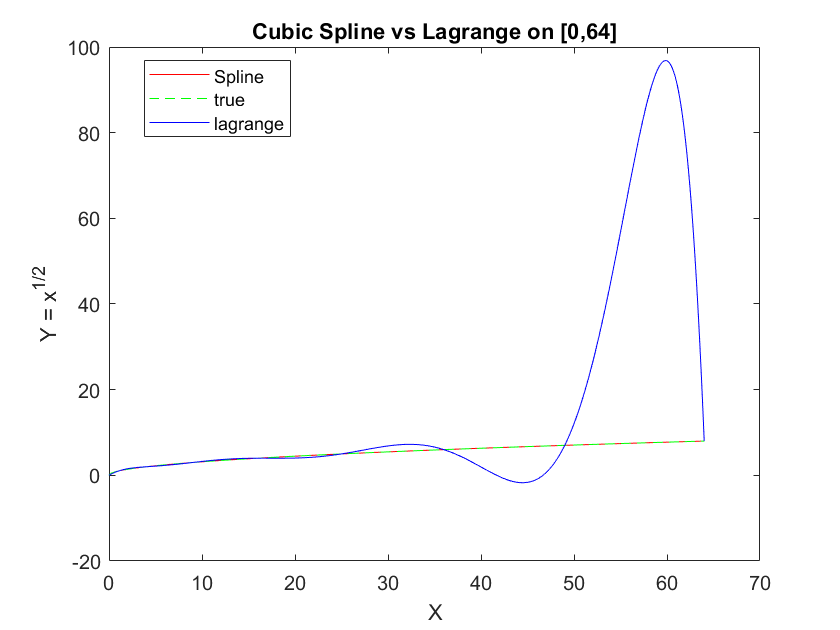

plot(0:0.1:64,y,"r-")
hold on;
plot(v,v.^0.5,"g--")
legend({'Spline','true'},'Location','best')
title('Cubic Spline interpolation on [0,64]')

xlabel('X')
ylabel('Y = x^{1/2}')
hold off;

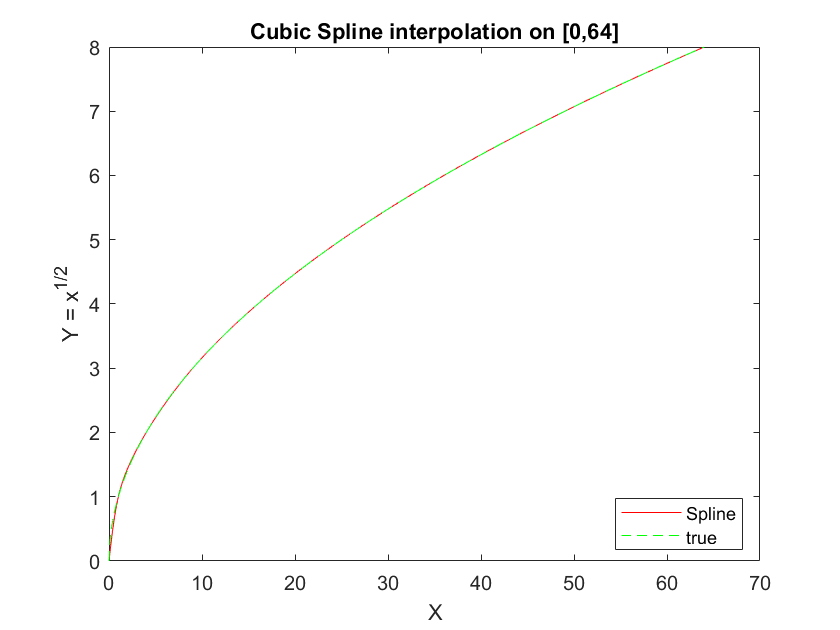

err_spl0 = y - (0:0.1:64).^(0.5);
plot(0:0.1:64,err_spl0);
grid;
legend({'error'},'location','best')
title('error of cubic spline on [0,64]')
xlabel('X')

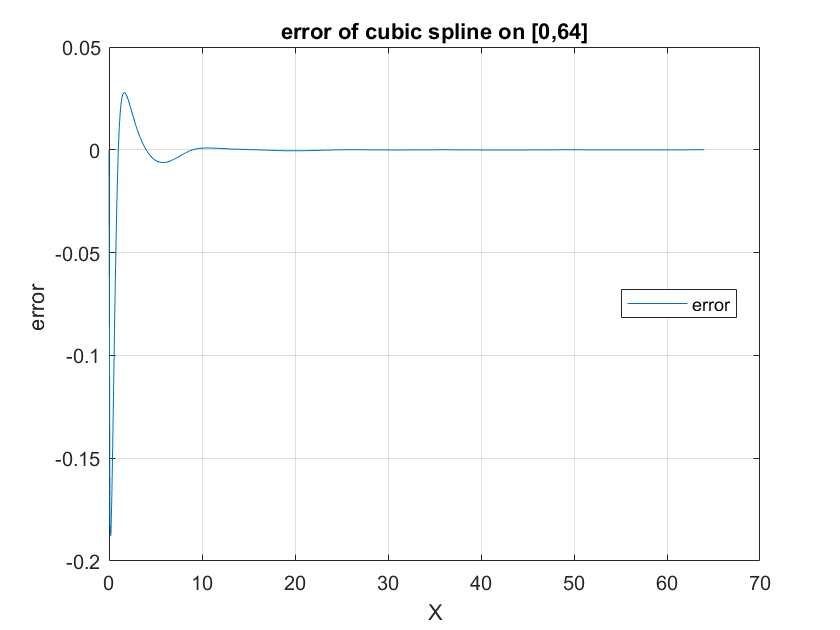

ylabel('error ')